judp('send', 8080, '192.168.178.100', int8(101))

MSSG = judp('RECEIVE', 8080, 600)

MSSG = 600×1 int8 column vector
   -72
   -67
   -76
   -77
   -68
   -32
   -63
   -34
   -48
   -80


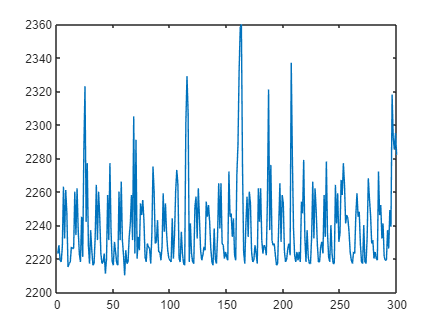


X = int16(MSSG);
for i= 1:600
    if (X(i) < 0)
        X(i) = X(i) + 255;
    else
        X(i) = X(i);
    end
end
X0 = X(1:300);
X1 = X(301:600);
y = X1 * 255 + X0;

plot(y)


save('ts_checking2.mat','y');